**Load golf ball data**

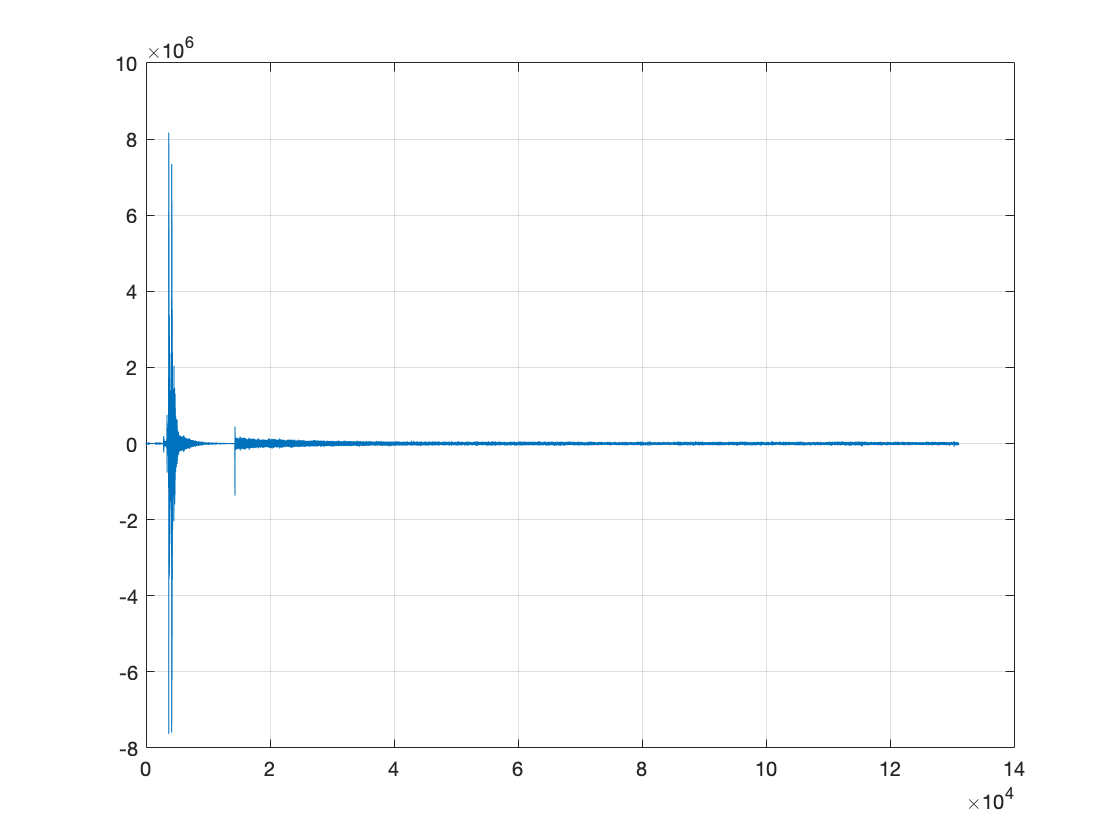

close all;
clear;

% Load golf shot data
filename = 'driver_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 16384; %FFT length
L = 3410; %Window length
overlap = floor(0.95*L); % 95% overlap
W = blackman(L);

**Signal data:**

% SIGNAL
signal = GolfBallData;

**Calling Spectrogram function:**

%Spectrogram 

[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,W,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames

**Plotting Spectrogram:**

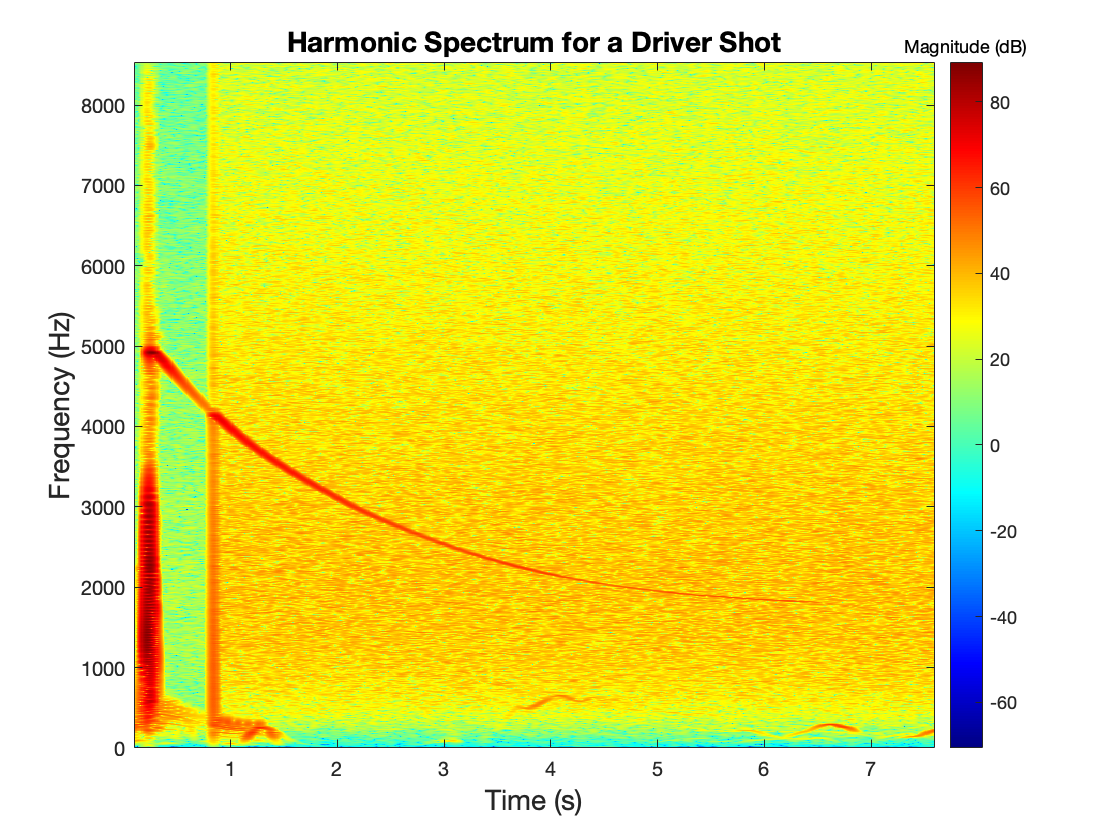

%Plotting Spectrogram
imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("Harmonic Spectrum for a Driver Shot",'FontSize', 14);
xlabel("Time (s)",'FontSize', 14);
ylabel("Frequency (Hz)",'FontSize', 14);

**Plot frame at 0.32 seconds:**

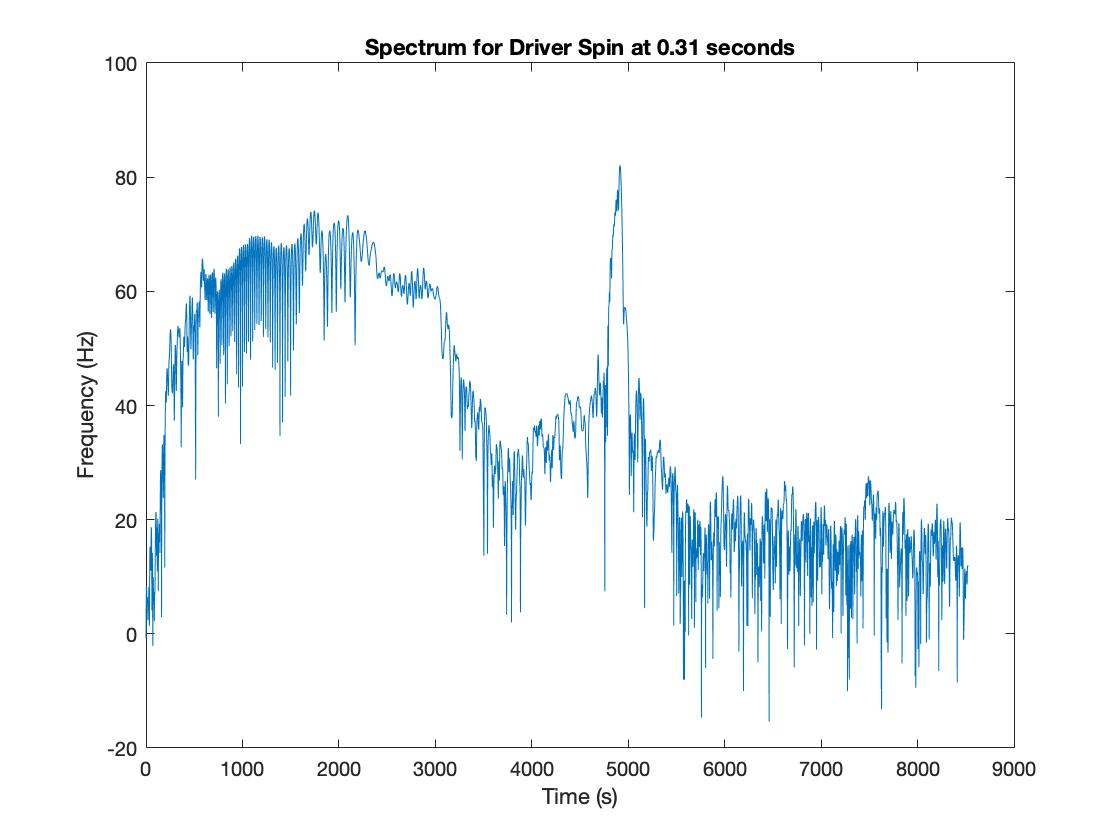

plot(freq,Spec_mag(:,22))
title("Spectrum for Driver Spin at 0.31 seconds"), xlabel("Time (s)"),ylabel("Frequency (Hz)");